b747_state_space;

B_elevator = B_lon(:, 1);
ol_sys = ss(A_lon, B_elevator, [0 0 0 1], [])

ol_sys =
 
  A = 
              x1         x2         x3         x4
   x1  -0.006868    0.01395          0      -32.2
   x2   -0.09055    -0.3151        774          0
   x3  0.0001187  -0.001026    -0.4285          0
   x4          0          0          1          0
 
  B = 
              u1
   x1  -0.000187
   x2     -17.85
   x3     -1.158
   x4          0
 
  C = 
       x1  x2  x3  x4
   y1   0   0   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


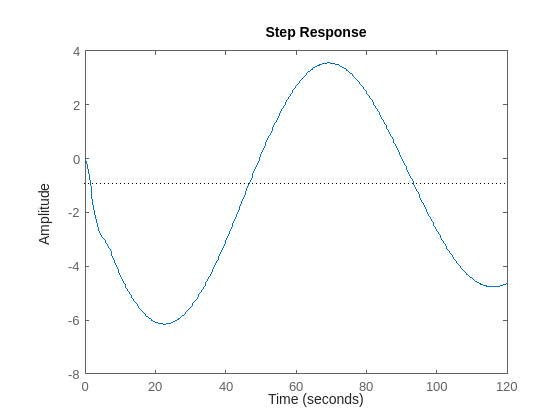


figure(1);
step(ol_sys, 120);

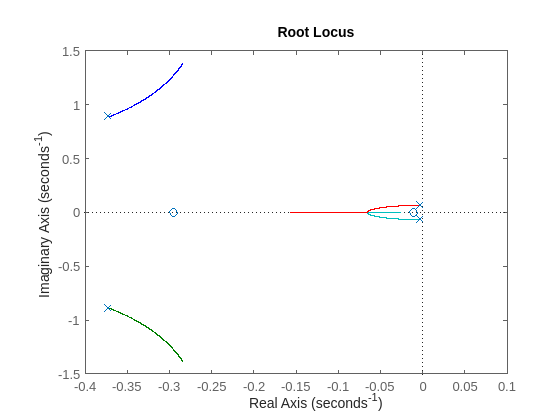

rlocus(ol_sys, 0:-0.001:-1);

## Step 1: Add feedback

k = -3.1;
J = k;

p_sys = feedback(J*ol_sys, 1)

p_sys =
 
  A = 
              x1         x2         x3         x4
   x1  -0.006868    0.01395          0      -32.2
   x2   -0.09055    -0.3151        774     -55.34
   x3  0.0001187  -0.001026    -0.4285      -3.59
   x4          0          0          1          0
 
  B = 
              u1
   x1  -0.000187
   x2     -17.85
   x3     -1.158
   x4          0
 
  C = 
         x1    x2    x3    x4
   y1     0     0     0  -3.1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


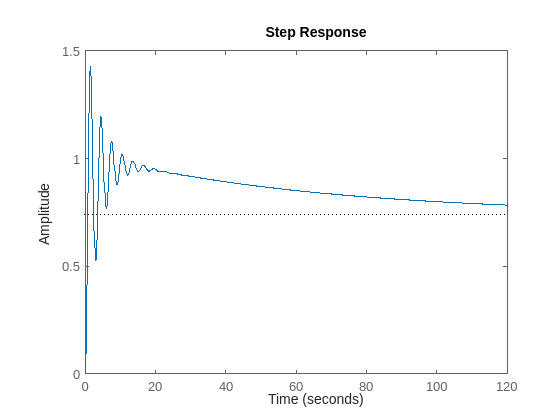


step(p_sys, 120);

## Step 2: Add integrator

s = tf('s');

% rlocus(ol_sys, 0:-0.001:-1);

J = -0.5 * (1 + 1/s);

pi_sys = feedback(J*ol_sys, 1)

pi_sys =
 
  A = 
              x1         x2         x3         x4         x5
   x1          0          0          0          0        0.5
   x2  -0.000187  -0.006868    0.01395          0      -32.2
   x3     -17.85   -0.09055    -0.3151        774     -8.925
   x4     -1.158  0.0001187  -0.001026    -0.4285     -0.579
   x5          0          0          0          1          0
 
  B = 
              u1
   x1          0
   x2  -0.000187
   x3     -17.85
   x4     -1.158
   x5          0
 
  C = 
         x1    x2    x3    x4    x5
   y1    -1     0     0     0  -0.5
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


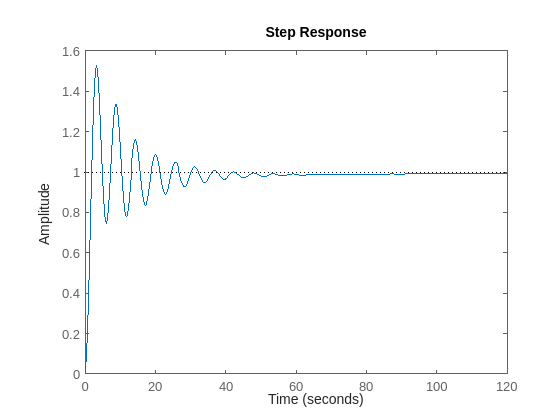


step(pi_sys, 120);

ss(pi_sys)

## Step 3: Add derivative

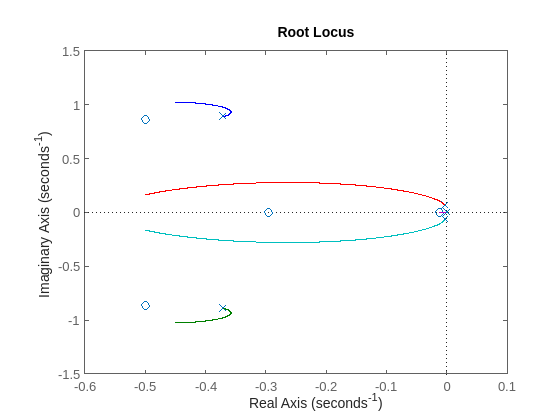

rlocus(ol_sys*(1 + 1/s + s), 0:-0.001:-1);

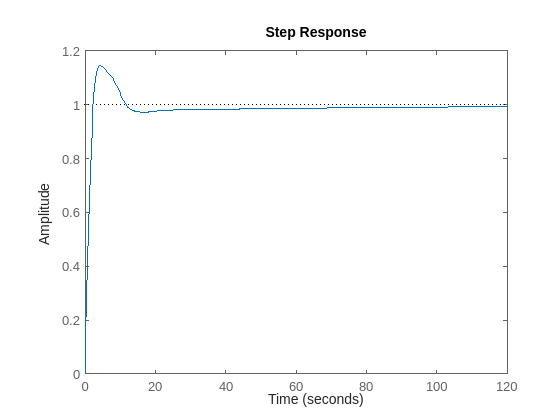

J = -0.5 * (1 + 1/s + 1*s);
pid_sys = feedback(J*ol_sys, 1);

step(pid_sys, 120);

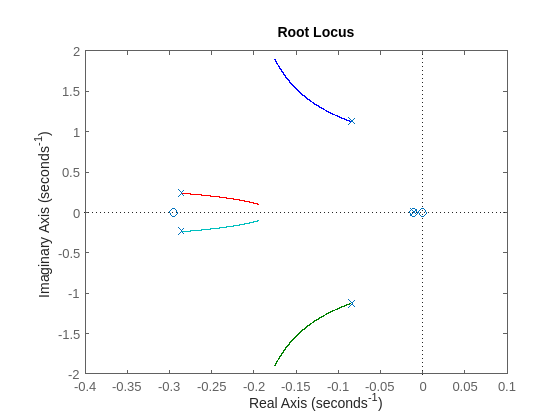

kp = -0.5;
ki = -0.5;
% G = ol_sys/(1 + (kp + ki/s)*ol_sys);
G = feedback(ol_sys, kp+ki/s);
rlocus(G, 0:-0.001:-2)